# **MODELADO DE SISTEMAS DINÁMICOS**

### Máster en Ingeniería Matemática y Computación

Exámen Final

***Autor***: Javier E. Blanco A.

clear, clc
sim = sim("Exam_sim.slx");


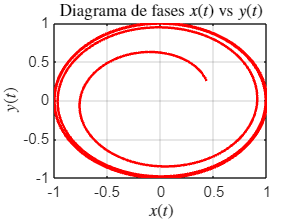

x = sim.simout.Data(:,1);
y = sim.simout.Data(:,2);

figure
plot(x,y, "Color",'r', 'LineStyle','-', LineWidth=1.5);
xlabel('$x(t)$', Interpreter='latex');
ylabel('$y(t)$', Interpreter='latex');
title('Diagrama de fases $x(t)$ vs $y(t)$', Interpreter='latex');
grid on;

syms r theta

f_r = @(r) r.*(r-1).*(r-2);
g_theta = @(theta) pi;


pe_f = solve(f_r, r)

$$pe\_f = \left(\begin{array}{c} 0\\ 1\\ 2 \end{array}\right)$$

pe_g = solve(g_theta, r)

 
pe_g =
 
Empty sym: 0-by-1
 



jaco = jacobian(r*(r-1)*(r-2), r)

$$jaco = \left(r-1\right)\,\left(r-2\right)+r\,\left(r-1\right)+r\,\left(r-2\right)$$

traza = trace(jaco)

$$traza = \left(r-1\right)\,\left(r-2\right)+r\,\left(r-1\right)+r\,\left(r-2\right)$$

deter = det(jaco)

$$deter = 3\,r^{2}-6\,r+2$$


lambdas = eig(jaco)

$$lambdas = \left(r-1\right)\,\left(r-2\right)+r\,\left(r-1\right)+r\,\left(r-2\right)$$

clear, clc
sim_2 = sim("Exam_sim.slx");


Mapa discreto

syms x
mu = -1/4;
f = @(x) mu - x.^2;
df = diff(f,x);

pf = solve(f - x, x);

disp('Los puntos fijos del sistema son:\n')

Los puntos fijos del sistema son:\n


disp(pf);

$$\left(\begin{array}{c} -\frac{1}{2}\\ -\frac{1}{2} \end{array}\right)$$

Clasificamos los puntos para determinar la estabilidad

stability = zeros(size(pf));
for i=1:length(pf)
    fprintf('Punto fijo: x = %.4f, es: ', double(pf(i)));
    stability(i) = subs(df, x, pf(i));
        if abs(stability(i)) < 1
            disp('Estable');
        elseif abs(stability(i)) > 1
            disp('Inestable');
        else
            disp('Indeterminada');
        end
end

Punto fijo: x = -0.5000, es: 

Indeterminada


Punto fijo: x = -0.5000, es: 

Indeterminada


disp(stability)

     1
     1



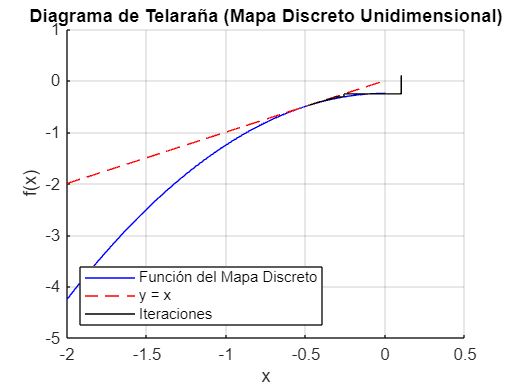

x_range = linspace(-2, 0, 1000);
num_iterations = 50;

% Visualizar el diagrama de telaraña
figure;
hold on;

% Plotear la función del mapa discreto
plot(x_range, f(x_range), 'b');

% Plotear la línea diagonal y=x
plot(x_range, x_range, 'r--');

% Realizar las iteraciones del mapa discreto
x_init = 0.1; % Punto inicial arbitrario
for i = 1:num_iterations
    x_next = f(x_init);
    % Trazar la línea que conecta los puntos (x, f(x)) y (f(x), f(x))
    plot([x_init, x_init], [x_init, x_next], 'k');
    plot([x_init, x_next], [x_next, x_next], 'k');
    x_init = x_next;
    drawnow;
end

xlabel('x');
ylabel('f(x)');
title('Diagrama de Telaraña (Mapa Discreto Unidimensional)');
legend('Función del Mapa Discreto', 'y = x', 'Iteraciones','Location', 'southwest');
grid on;

3) Integrales por Montecarlo

clear, clc
format shortG

seed = 142;
rng(seed);
V_mc = 0;

iterations = 10000;
x_1 = 0;
% x_2 = @(y) y/2 + 1;
% x_2 = @(y) (6-y) / 2;
% x_2 = @(y) sqrt(y);
% x_2 = @(y) (1/2).*sqrt(1 - 3.*y.^2);
x_2 = @(y) 1;
y_1 = 0;
y_2 = 2;

% fg = @(x,y) exp(x + y).*(sin(pi*y).^2);
% fg = @(x,y) (x-y).^2;
% fg = @(x,y) 1/((y.^(1/3)).*(x.^3 + 1))
% fg = @(x,y) x.*y.^2;
% fg = @(x,y) (1 - 4.*x.^2 - 3.*y.^2).^(1/2);
fg = @(x,y) (2.*x + y).^8;
% **** MONTECARLO ******
for i=1:iterations
    y_int = (y_2 - y_1) .* rand() + y_1;
    x_int = ((x_2(y_int)) - x_1) .* rand() + x_1;
    fv = fg(x_int, y_int);
    Vhp = (x_2(y_int) - x_1)*(y_2 - y_1);
    V_mc = V_mc+fv*Vhp;
end

V_mc = V_mc/iterations

V_mc =        5812.5


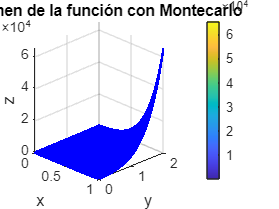



% ****** PLOT ***************
y_int = (y_2 - y_1) .* rand(iterations, 1) + y_1;
x_int = ((x_2(y_int)) - x_1) .* rand(iterations, 1) + x_1;
fv = fg(x_int, y_int);

figure;
hold on;
scatter3(x_int, y_int, fv, 2, 'blue', 'filled')
[X,Y] = meshgrid(linspace(min(x_int), max(x_int),50), linspace(y_1, y_2, 50));
Z = fg(X,Y);
surf(X, Y, Z, 'FaceAlpha', 0.5, 'EdgeColor', 'none')
colormap(parula); % Profesional colormap
colorbar; % Colorbar
% pcolor(X, Y, Z);
shading interp;
xlabel('x')
ylabel('y')
zlabel('z')
view(45,20)
title('Volumen de la función con Montecarlo');
grid on;

% fg2 = @(x,y) (sin(pi*x).^2) .* exp(x + y);
fg2 = @(x,y) (2.*x + y).^8;
integral2(fg2, x_1, 1, y_1, y_2)

ans =          5814
